# Example 7.8: Conflict Resolution in Generator Sizing

Note: this script reproduces Example 7.8 (Section 7.6.2) of **Statistics for Chemical Engineers**: the trade-off between expected cost and cost variability, and CVaR for different alpha. Victor Z UW-Madison, 2022 generator sizing example explore conflict resolution (mean vs. variance)

clc; clear all; close all hidden;

## Load scenarios and mean-variance trade-off

generate scenarios for random load

rng(0)
N=1000;
X=wblrnd(10,2,N,1);


 lb = 0; ub=+10; %upper bound for sizes 
opt = optimoptions('fmincon','Display','iter','Algorithm','sqp');
 u0 = 1;
kappa = 0:1:15;
  
for k=1:length(kappa)
    
    u(k) = fmincon(@myfun,u0,[],[],[],[],lb,ub,[],opt,X,kappa(k));
 rho1(k) = myfun1(u(k),X);
 rho2(k) = myfun2(u(k),X);
 
end

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order   Wall-Clock Time  
                                                                       step    optimality
    0           2    4.315131e+02     0.000e+00     1.000e+00     0.000e+00     4.979e+01      0.049230 sec  
    1           8    4.167119e+02     0.000e+00     2.401e-01     2.161e+00     4.562e+01      0.064550 sec  
    2          10    4.003950e+02     0.000e+00     1.000e+00     9.042e-01     2.043e-01      0.066126 sec  
    3          12    4.003945e+02     0.000e+00     1.000e+00     5.186e-03     1.079e-03      0.067634 sec  
    4          14    4.003945e+02     0.000e+00     1.000e+00     2.725e-05     3.388e-06      0.069118 sec  
    5          15    4.003945e+02     0.000e+00     7.000e-01     5.971e-08     3.388e-06      0.070197 sec  

Local minimum possible. Constraints satisfied.

fmin

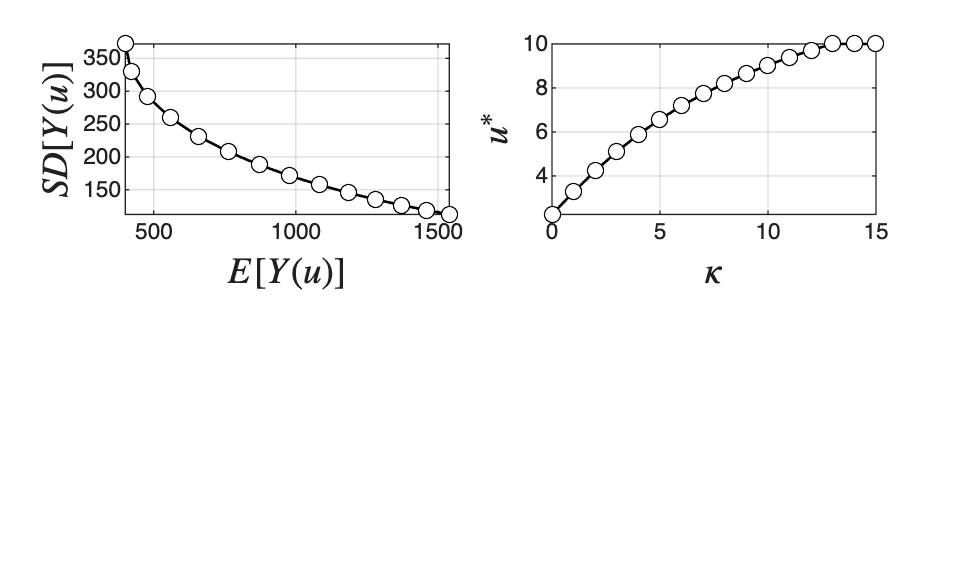


figure(1)
subplot(2,2,1)
plot(rho1,rho2,'LineWidth',1,'Color','black','LineStyle','-')
hold on
scatter(rho1,rho2,'MarkerFaceColor','w','MarkerEdgeColor','black')
grid on
hold on
xlabel('$E[Y(u)]$','Interpreter','latex','FontSize',14)
ylabel('$SD[Y(u)]$','Interpreter','latex','FontSize',14)
axis([min(rho1) max(rho1) min(rho2) max(rho2)])
subplot(2,2,2)
plot(kappa,u,'LineWidth',1,'Color','black','LineStyle','-')
hold on
scatter(kappa,u,'MarkerFaceColor','w','MarkerEdgeColor','black')
grid on
hold on
xlabel('$\kappa$','Interpreter','latex','FontSize',14)
ylabel('$u^*$','Interpreter','latex','FontSize',14)
axis([min(kappa) max(kappa) min(u) max(u)])

## CVaR for different alpha

now span CVaR with alpha

alpha = 0:0.1:1;
u=[];
rho1=[];
rho2=[];
u0=1;
for k=1:length(alpha)
    
    u(k) = fmincon(@myfun3,u0,[],[],[],[],lb,ub,[],opt,X,alpha(k));
 rho1(k) = myfun1(u(k),X);
 rho2(k) = myfun2(u(k),X);
     u0  = u(k)
 
end

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order   Wall-Clock Time  
                                                                       step    optimality
    0           2    4.315131e+02     0.000e+00     1.000e+00     0.000e+00     4.979e+01      0.020690 sec  
    1           8    4.167119e+02     0.000e+00     2.401e-01     2.161e+00     4.562e+01      0.027634 sec  
    2          10    4.003950e+02     0.000e+00     1.000e+00     9.042e-01     2.043e-01      0.029927 sec  
    3          12    4.003945e+02     0.000e+00     1.000e+00     5.186e-03     1.079e-03      0.031937 sec  
    4          14    4.003945e+02     0.000e+00     1.000e+00     2.725e-05     3.388e-06      0.033752 sec  
    5          15    4.003945e+02     0.000e+00     7.000e-01     5.971e-08     3.388e-06      0.035167 sec  

Local minimum possible. Constraints satisfied.

fmin

u0 = 2.2516

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order   Wall-Clock Time  
                                                                       step    optimality
    0           2    4.362560e+02     0.000e+00     1.000e+00     0.000e+00     7.078e+00      0.008288 sec  
    1          13    4.358660e+02     0.000e+00     4.035e-02     2.856e-01     4.347e+00      0.013925 sec  
    2          15    4.356298e+02     0.000e+00     1.000e+00     1.087e-01     1.571e-06      0.015573 sec  
    3          16    4.356298e+02     0.000e+00     7.000e-01     2.749e-08     1.571e-06      0.016825 sec  

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the 

u0 = 2.4285

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order   Wall-Clock Time  
                                                                       step    optimality
    0           2    4.764949e+02     0.000e+00     1.000e+00     0.000e+00     6.655e+00      0.007556 sec  
    1          13    4.761500e+02     0.000e+00     4.035e-02     2.686e-01     4.087e+00      0.013180 sec  
    2          15    4.759412e+02     0.000e+00     1.000e+00     1.022e-01     1.470e-06      0.014776 sec  
    3          17    4.759412e+02     0.000e+00     1.000e+00     3.675e-08     7.350e-06      0.016285 sec  

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the 

u0 = 2.5949

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order   Wall-Clock Time  
                                                                       step    optimality
    0           2    5.228472e+02     0.000e+00     1.000e+00     0.000e+00     6.787e+00      0.008605 sec  
    1          13    5.224886e+02     0.000e+00     4.035e-02     2.739e-01     4.168e+00      0.013725 sec  
    2          15    5.222714e+02     0.000e+00     1.000e+00     1.042e-01     0.000e+00      0.015582 sec  

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisf

u0 = 2.7645

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order   Wall-Clock Time  
                                                                       step    optimality
    0           2    5.773161e+02     0.000e+00     1.000e+00     0.000e+00     7.287e+00      0.006009 sec  
    1          13    5.768935e+02     0.000e+00     4.035e-02     2.920e-01     4.394e+00      0.008734 sec  
    2          15    5.766523e+02     0.000e+00     1.000e+00     1.098e-01     2.589e-06      0.009806 sec  
    3          17    5.766523e+02     0.000e+00     1.000e+00     6.473e-08     2.589e-06      0.010787 sec  

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the 

u0 = 2.9467

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order   Wall-Clock Time  
                                                                       step    optimality
    0           2    6.416115e+02     0.000e+00     1.000e+00     0.000e+00     7.840e+00      0.009114 sec  
    1          13    6.410004e+02     0.000e+00     4.035e-02     2.846e-01     3.577e+00      0.011753 sec  
    2          15    6.408432e+02     0.000e+00     1.000e+00     8.863e-02     9.711e-06      0.063470 sec  
    3          17    6.408432e+02     0.000e+00     1.000e+00     2.428e-07     2.428e-06      0.064512 sec  

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the 

u0 = 3.1427

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order   Wall-Clock Time  
                                                                       step    optimality
    0           2    7.204320e+02     0.000e+00     1.000e+00     0.000e+00     8.831e+00      0.006459 sec  
    1          12    7.200663e+02     0.000e+00     5.765e-02     3.953e-01     7.095e+00      0.008961 sec  
    2          14    7.194571e+02     0.000e+00     1.000e+00     1.745e-01     4.537e-06      0.009963 sec  
    3          16    7.194571e+02     0.000e+00     1.000e+00     1.134e-07     2.268e-06      0.011207 sec  

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the 

u0 = 3.3635

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order   Wall-Clock Time  
                                                                       step    optimality
    0           2    8.197404e+02     0.000e+00     1.000e+00     0.000e+00     1.017e+01      0.005028 sec  
    1          12    8.187776e+02     0.000e+00     5.765e-02     3.826e-01     5.339e+00      0.007722 sec  
    2          14    8.184480e+02     0.000e+00     1.000e+00     1.284e-01     0.000e+00      0.008756 sec  

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisf

u0 = 3.6177

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order   Wall-Clock Time  
                                                                       step    optimality
    0           2    9.493057e+02     0.000e+00     1.000e+00     0.000e+00     1.190e+01      0.006103 sec  
    1          11    9.485786e+02     0.000e+00     8.235e-02     5.256e-01     9.583e+00      0.008660 sec  
    2          13    9.475369e+02     0.000e+00     1.000e+00     2.282e-01     0.000e+00      0.009667 sec  

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisf

u0 = 3.9151

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order   Wall-Clock Time  
                                                                       step    optimality
    0           2    1.156667e+03     0.000e+00     1.000e+00     0.000e+00     1.680e+01      0.005471 sec  
    1          10    1.154890e+03     0.000e+00     1.176e-01     7.159e-01     1.310e+01      0.007974 sec  
    2          12    1.153139e+03     0.000e+00     1.000e+00     2.959e-01     3.520e-06      0.009171 sec  
    3          13    1.153139e+03     0.000e+00     7.000e-01     6.160e-08     3.520e-06      0.010117 sec  

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the 

u0 = 4.3351

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order   Wall-Clock Time  
                                                                       step    optimality
    0           2    2.962697e+03     0.000e+00     1.000e+00     0.000e+00     1.015e+02      0.007382 sec  
    1           5    2.874703e+03     0.000e+00     7.000e-01     3.965e+00     1.242e+02      0.009935 sec  
    2           7    2.833922e+03     0.000e+00     1.000e+00     1.428e+00     4.440e-06      0.011021 sec  
    3           9    2.833922e+03     0.000e+00     1.000e+00     1.110e-07     8.881e-06      0.012060 sec  

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the 

u0 = 6.8726

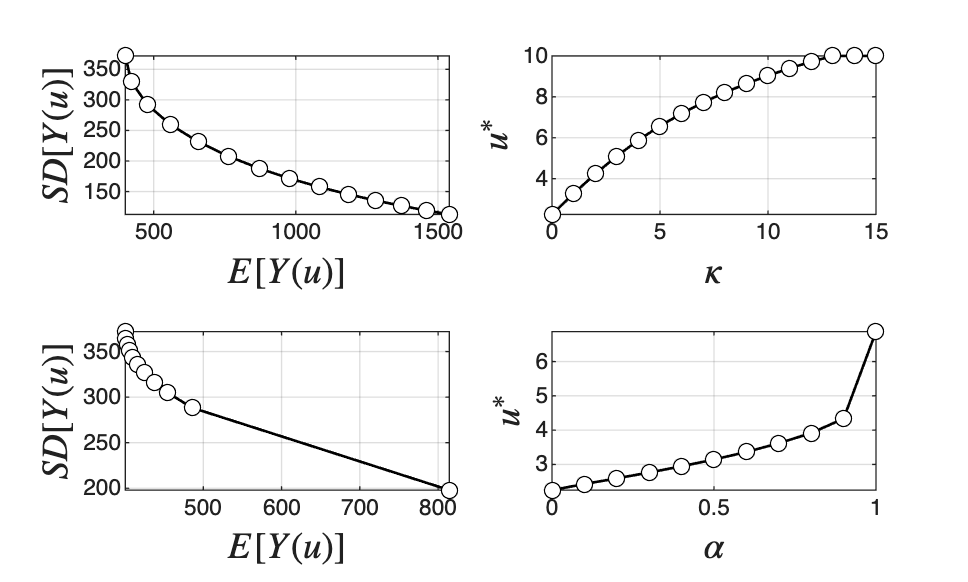


figure(1)
subplot(2,2,3)
plot(rho1,rho2,'LineWidth',1,'Color','black','LineStyle','-')
hold on
scatter(rho1,rho2,'MarkerFaceColor','w','MarkerEdgeColor','black')
grid on
hold on
xlabel('$E[Y(u)]$','Interpreter','latex','FontSize',14)
ylabel('$SD[Y(u)]$','Interpreter','latex','FontSize',14)
axis([min(rho1) max(rho1) min(rho2) max(rho2)])
subplot(2,2,4)
plot(alpha,u,'LineWidth',1,'Color','black','LineStyle','-')
hold on
scatter(alpha,u,'MarkerFaceColor','w','MarkerEdgeColor','black')
grid on
hold on
xlabel('$\alpha$','Interpreter','latex','FontSize',14)
ylabel('$u^*$','Interpreter','latex','FontSize',14)
axis([min(alpha) max(alpha) min(u) max(u)])
print -depsc ch7_generator_conflict.eps


% combined risk measure
function rho = myfun(u,X,kappa)
 
rho1 = myfun1(u,X);
rho2 = myfun2(u,X);
 rho = rho1 + kappa*rho2;
 
end

% risk measure 1
function rho1 = myfun1(u,X)
 
   R = max(X-u,0);
   y = 5*(R.^2) + 15*u.^2;
rho1 = mean(y);
 
end
 
% risk measure 2
function rho2 = myfun2(u,X)
 
   R = max(X-u,0);
   y = 5*(R.^2) + 15*u.^2;
rho2 = std(y);

end

% cvar
function rho3 = myfun3(u,X,alpha)
 
   R = max(X-u,0);
   y = 5*(R.^2) + 15*u.^2;
   
   Q = quantile(y,alpha);
 loc = y >= Q;
rho3 = mean(y(loc));

end

## Note

As in the book, the mean-variance trade-off can give inconsistent or very conservative solutions (a large generator), while CVaR controls large costs directly (alpha = 1 gives the worst case).